# 一様乱数の生成と頻度分布の描画

clear all;
license('inuse')

matlab
statistics_toolbox


## １．乱数を生成する

### １．１　一様乱数の生成

Q1. 0 から 1までの一様乱数を5個出力せよ。

rand([1 5])

ans =     0.8147    0.9058    0.1270    0.9134    0.6324


または

unifrnd(0, 1, [1 5])

ans =     0.0975    0.2785    0.5469    0.9575    0.9649


### １．２　整数の一様乱数

Q2. `[-3,4]` の一様分布したランダムな整数を5個出力せよ。

randi([-3,4], [1 5])

ans =     -2     4     4     0     3


ans =    -0.2050   -0.1241    1.4897    1.4090    1.4172


## ２．度数分布の描画

### ２．１　乱数列をデータとして、変数に格納する

Q3. 0 から 1までの一様乱数を10000個出力し、変数 data1 に格納せよ。

data1 = rand([1 10000])

data1 =     0.1452    0.6158    0.7982    0.8202    0.3686    0.8099    0.0607    0.0908    0.8056    0.5470    0.8951    0.1869    0.8325    0.0626    0.6000    0.0601    0.2335    0.2197    0.2593    0.5993    0.6949    0.9221    0.6556    0.6336    0.4018    0.3578    0.4540    0.8389    0.3900    0.8897    0.8114    0.8223    0.8649    0.3387    0.0633    0.2669    0.0926    0.6713    0.9449    0.6563    0.4164    0.2416    0.3510    0.6997    0.4887    0.8204    0.3300    0.0941    0.8318    0.4267


Q4. `[-5, 10]` の一様分布したランダムな整数を10000個出力し、変数 data2 に格納せよ。

data2 = randi([-5,10], [1 10000])

data2 =      4     3    -5     3    -1     2    -2     9    -2     5    -2     5    -1     1    10    -4     7    10    -4     6     5     0     5     5    -2     5    -1     9     6     2     1     7    -1    10     2     5     0     1     3    -3     3     2     6    10     2    10     3    -2     3    -5


### ２．２　度数分布の描画

Q5. data1 の度数分布を描画せよ。

h1 = histogram(data1)

h1 =   Histogram のプロパティ:

             Data: [0.1452 0.6158 0.7982 0.8202 0.3686 0.8099 0.0607 0.0908 0.8056 0.5470 0.8951 0.1869 0.8325 0.0626 0.6000 0.0601 0.2335 0.2197 0.2593 0.5993 0.6949 0.9221 0.6556 0.6336 0.4018 0.3578 0.4540 0.8389 0.3900 0.8897 … ] (1×10000 double)
           Values: [492 531 515 497 496 537 479 530 497 468 491 483 502 530 473 496 481 512 498 492]
          NumBins: 20
         BinEdges: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1]
         BinWidth: 0.0500
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示


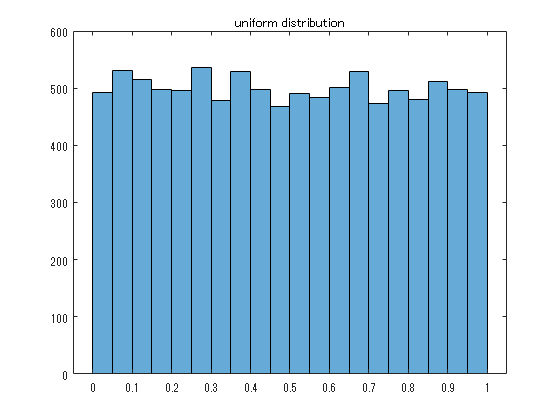

title('uniform distribution')

Q6. data2 の度数分布を描画せよ。

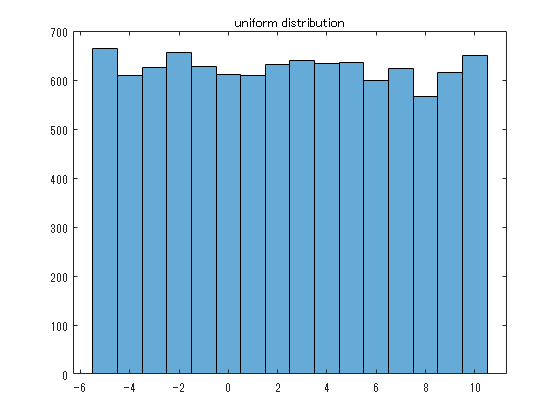

h2 = histogram(data2);
title('uniform distribution')

## 例題

Q7. $-1$ から $+1$までの一様乱数を1000個出力し、それらの度数分布を描画せよ。

Q8. `[-2, 15]` の一様分布したランダムな整数を1000個出力し、それらの度数分布を描画せよ。

## 参考文献

- [https://jp.mathworks.com/help/matlab/ref/rand.html](https://jp.mathworks.com/help/matlab/ref/rand.html)

- [https://jp.mathworks.com/help/matlab/ref/randi.html](https://jp.mathworks.com/help/matlab/ref/randi.html)

- [https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)